# Laboratorio Señales

## Filtros

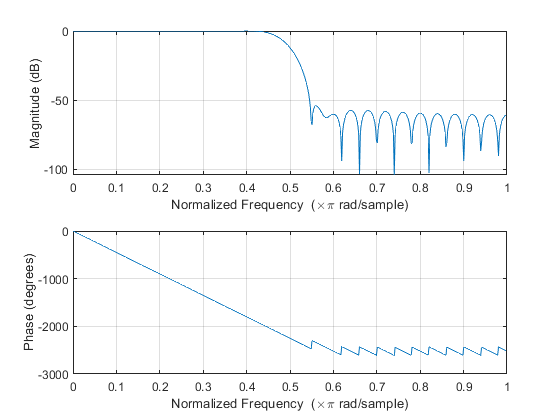

f_mues=1000;

n=0:499;

xn=cos(n*2*pi*200/f_mues)+cos(n*2*pi*150/f_mues)...
    + cos(n*2*pi*280/f_mues);


fb=fir1(50,240/(f_mues*0.5));
freqz(fb)


xk=abs(fft(xn)/(f_mues*0.5))

xk =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


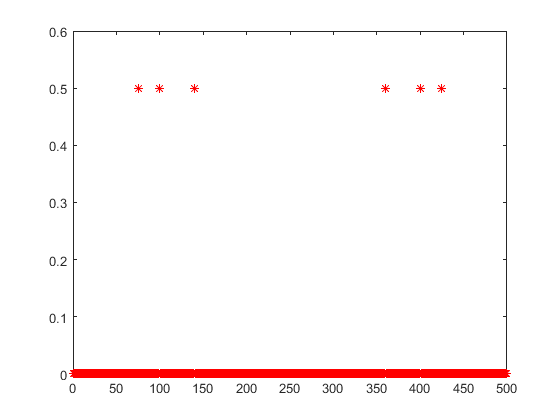

figure
plot(n, xk,'*r')


yn=filter(fb,1,xn)

yn =    -0.0000   -0.0033   -0.0013    0.0069    0.0044   -0.0106   -0.0089    0.0151    0.0155   -0.0211   -0.0264    0.0276    0.0433   -0.0325   -0.0670    0.0344    0.0987   -0.0326   -0.1441    0.0260    0.2194   -0.0099   -0.3811   -0.0321    1.0966    1.7217    0.7526   -1.0278   -1.6862   -0.5475    0.9509    1.1459    0.1799   -0.5149   -0.3092    0.0053   -0.2552   -0.4993    0.1243    1.1143    1.0138   -0.4943   -1.7711   -1.1258    0.9042    2.0085    0.8941   -1.1239   -1.7608   -0.4996


yk=abs(fft(yn))/(f_mues*0.5)

yk =     0.0040    0.0039    0.0039    0.0037    0.0036    0.0033    0.0031    0.0028    0.0026    0.0023    0.0022    0.0021    0.0021    0.0022    0.0024    0.0027    0.0031    0.0034    0.0037    0.0040    0.0042    0.0044    0.0045    0.0046    0.0046    0.0045    0.0043    0.0041    0.0038    0.0035    0.0031    0.0027    0.0024    0.0022    0.0022    0.0025    0.0029    0.0035    0.0041    0.0047    0.0053    0.0058    0.0062    0.0066    0.0069    0.0070    0.0070    0.0069    0.0066    0.0062


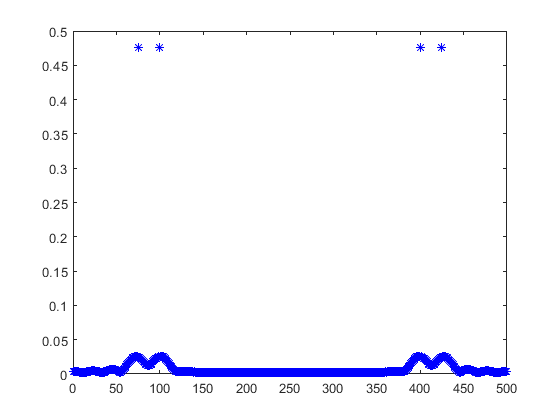

plot(n,yk,'*b')

hold off

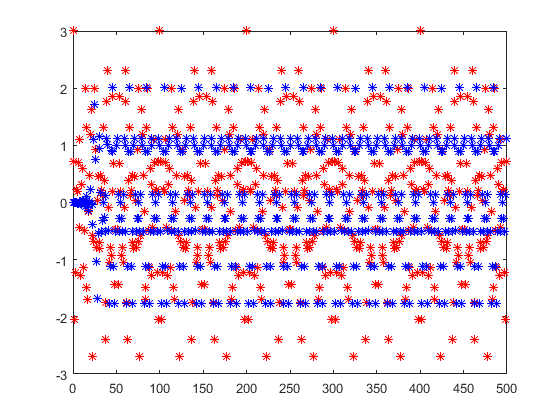


figure
plot(n,xn,'*r')
hold on
plot(n,yn,'*b')

## IIR

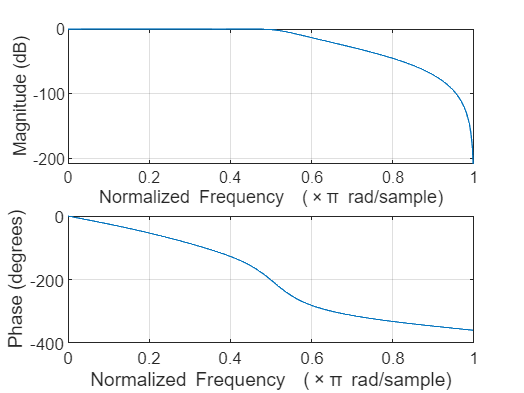

[fb1 , fa1] = butter(4,240/500);
[fb1 , fa1] = cheby1(4,0.2,240/500);

freqz(fb1, fa1)


yn1=filter(fb,fa1,xn)

yn1 =    -0.0000   -0.0033   -0.0027    0.0085    0.0091   -0.0141   -0.0192    0.0202    0.0343   -0.0273   -0.0573    0.0337    0.0917   -0.0356   -0.1393    0.0286    0.2023   -0.0089   -0.2870   -0.0293    0.4137    0.1016   -0.6494   -0.2581    1.4975    2.3488    0.5168   -2.2351   -2.5024    0.1072    2.2940    1.5196   -0.7288   -1.3753   -0.0975    0.6891   -0.2170   -1.0214    0.0899    1.8349    1.4254   -1.2417   -2.9032   -1.1126    2.2570    3.1216    0.3640   -2.6977   -2.5013    0.3976



yk1=abs(fft(yn1))/(f_mues*0.5)

yk1 =     0.0043    0.0043    0.0042    0.0040    0.0037    0.0034    0.0030    0.0026    0.0021    0.0016    0.0011    0.0007    0.0008    0.0012    0.0018    0.0023    0.0029    0.0034    0.0038    0.0043    0.0046    0.0048    0.0050    0.0051    0.0051    0.0050    0.0048    0.0044    0.0040    0.0035    0.0029    0.0023    0.0016    0.0010    0.0009    0.0015    0.0023    0.0032    0.0041    0.0049    0.0057    0.0065    0.0071    0.0076    0.0080    0.0083    0.0084    0.0083    0.0080    0.0075


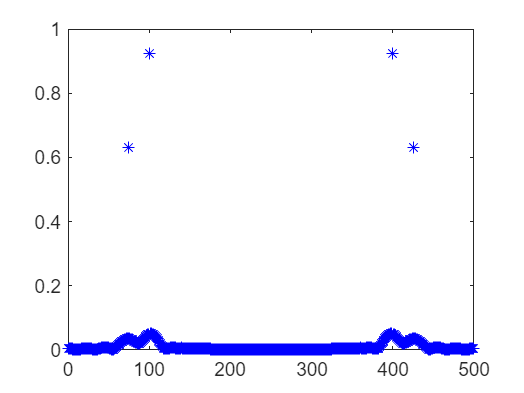

plot(n,yk1,'*b')


%se elige uno fir y uno ir para meterle al micro



%los irr son menos pesados computacionalmente



# Señales fisicas sensor

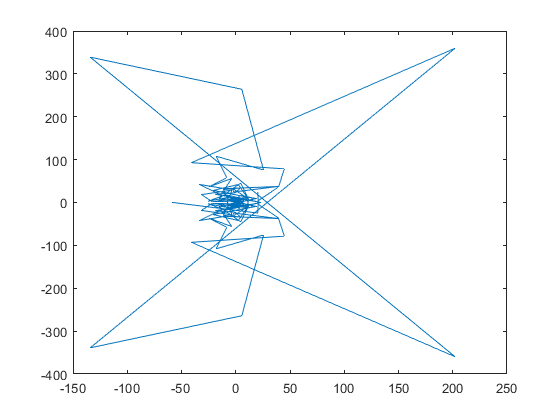

f_mues=400;
[xn , ~]=importdata( ...
    "./muestreo/muestras/acelymovladoalado01.txt");
xn=xn(200:1100);
n=[0:900]';
plot(fft(xn))

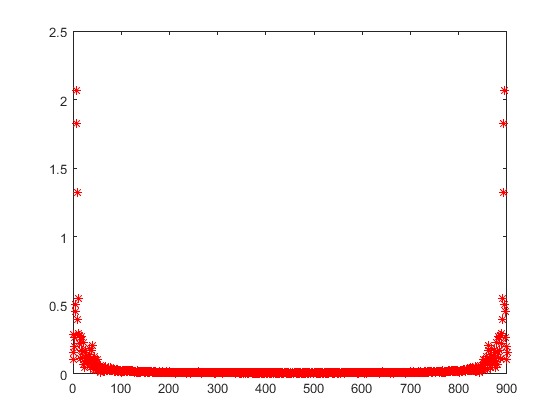

xk=abs(fft(xn)/(f_mues*0.5));
figure
plot(n, xk,'*r')

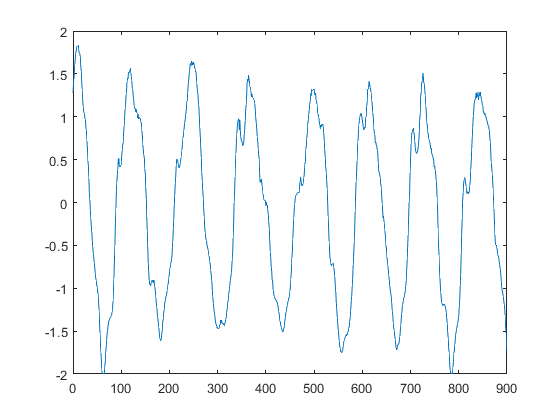

plot(n,xn)